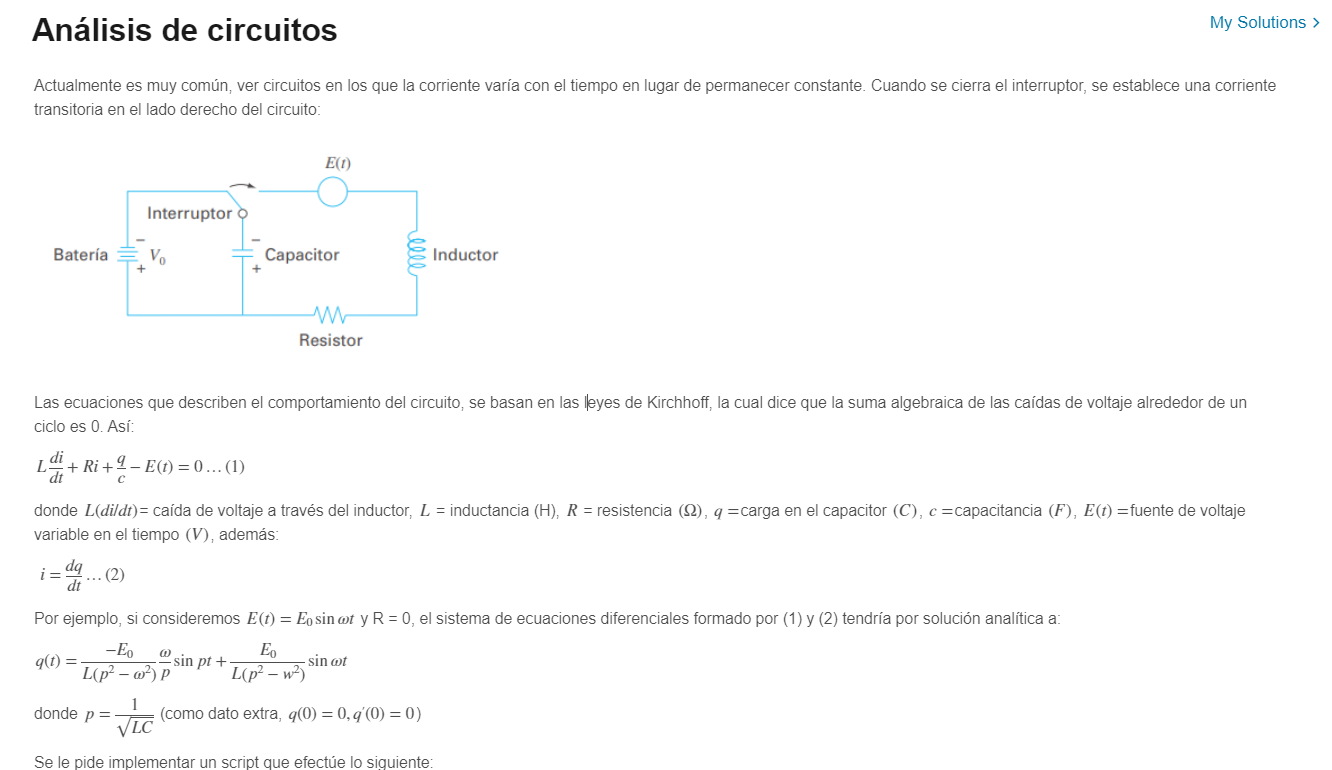

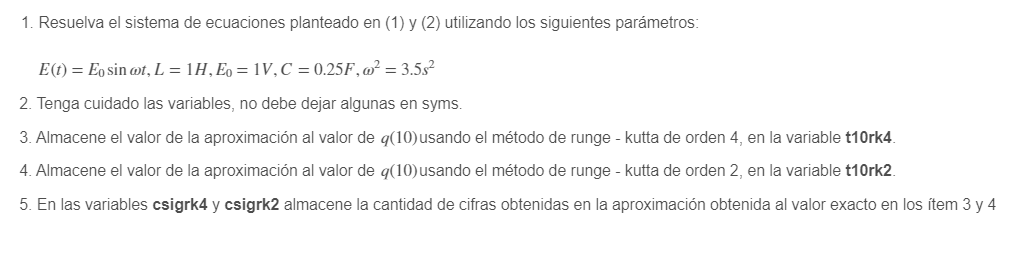

%primer item
%condiciones iniciales 
L = 1; E0 = 1; C = 0.25; w2 = 3.5; w = sqrt(w2); R = 0;
%funciones 
p = 1/sqrt(L*C);
q = @(t) (-E0./(L.*(p.^2-w.^2))).*(w./p).*sin(p.*t) + E0./(L.*(p.^2-w.^2)).*sin(w.*t);
solex=q(10)   %guarda la solucion exacta para t=10

solex = -1.9896

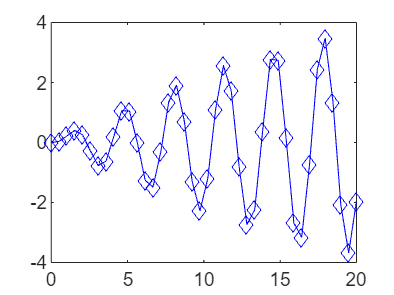

tt=linspace(0,20,40);
yy=q(tt);
tipo='-'; %completar en lugar de [];
marca= 'd'; %completar en lugar de [];
color='blue'; %completar en lugar de [];
caract=[tipo marca color];
p=plot(tt,yy,caract);


% d2q = -R/Ldq - q/(C*L) + E(t)/L
% q = u1
% dq = u2 = u'1
% u'2 = -R/L*u2 - 1/(C*L)*u1 + (E0 * sin(wt))/L
F = @(t, u) [u(2); -R/L*u(2) - 1/(C*L)*u(1) + (E0*sin(w*t))/L]

F = function_handle with value:
    @(t,u)[u(2);-R/L*u(2)-1/(C*L)*u(1)+(E0*sin(w*t))/L]


y0 = [0; 0];
h1 = 0.025; % ???
z1 = rk4(F, 0, 10, y0, h1);
t10rk4 = z1(end,2)

t10rk4 = -1.9896

h2 = 0.0125;
z2 =  Heun(F, 0, 10, y0, h2);
t10rk2 = z2(end, 2)

t10rk2 = -1.9882

er1 = abs(solex-t10rk4)/abs(solex)

er1 = 3.0745e-07

er2 = abs(solex-t10rk2)/abs(solex)

er2 = 6.7356e-04

csigrk4 = Cif_sig(er1)

csigrk4 = 7

csigrk2 = Cif_sig(er2)

csigrk2 = 3

function z=rk4(f,a,b,y0,h)
    t=[a:h:b];
    n=length(t);
    z=[t(1) y0'];
    for k=1:n-1
        k1=f(t(k),y0);
        k2=f(t(k)+h/2,y0+(h/2)*k1);
        k3=f(t(k)+h/2,y0+(h/2)*k2);
        k4=f(t(k)+h,y0+(h)*k3);
        y1=y0+(h/6)*(k1+2*k2+2*k3+k4);
        z=[z;t(k+1) y1'];
        y0=y1;
    end
end

function z = Heun(f, a, b, y0, h)
    t = [a:h:b];
    z = [t(1) y0'];
    for k = 1:length(t)-1
        k1 = h*f(t(k), y0);
        k2 = h*f(t(k+1), y0+k1);
        y1 = y0+1/2*(k1+k2);
        z = [z; t(k+1) y1'];
        y0 = y1;
    end
end

function CS = Cif_sig(Er)
    k=0;
    while Er <= 5*10^(-k)
        k = k+1;
    end
    CS = k-1;
end